# Lab 2

**Jessie Li // September 27, 2023**

## **2.A**

*Defining constant parameters (reused in 2.B)*

% Maximum number of iterations
MAX_ITER = 100;

% Tolerance = 2.2204e-16
% MATLAB's default for root-finding
% https://www.mathworks.com/help/matlab/math/setting-options.html#bt00l89-1
TOL = optimset('fzero').TolX;

% Interval
a = 1;
b = 2;

% Starting guess of root p
p0 = (a + b)/2;

*Graphing f(x) *

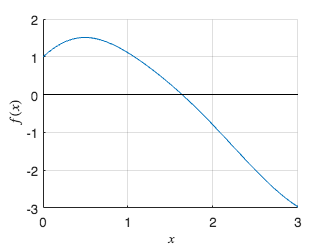

syms x
f = (x + cos(x)) * exp(-x^2) + x*cos(x);

% Graph of f(x)
figure
hold on

fplot(f, [0 3])
line([3,0], [0 0], 'Color', 'black'); % x axis
xlabel('$x$', 'interpreter', 'latex');
ylabel('$f(x)$', 'interpreter', 'latex');

grid on
hold off


% saveas(gcf, 'part-a-function.png');

*MATLAB's approximation of p, using built-in function *`fzero` (https://www.mathworks.com/help/matlab/ref/fzero.html)

p = fzero(matlabFunction(f), [a b]);
fprintf('p = %f', p);

p = 1.636723


fprintf('Expect f''(p) to be non-zero: %f', eval(subs(diff(f), p)));

Expect f'(p) to be non-zero: -2.051855

### 2.A.1 

g = x - f/diff(f);

lambda = eval(subs(diff(g, 2), p)) / 2;
fprintf('Expect alpha = 2');

Expect alpha = 2

fprintf('Expect g''(p) to be zero: %f', eval(subs(diff(g), p)));

Expect g'(p) to be zero: 0.000000

fprintf('Expect lambda for Newton to be g''''(p)/2: %f', lambda);

Expect lambda for Newton to be g''(p)/2: 0.230168

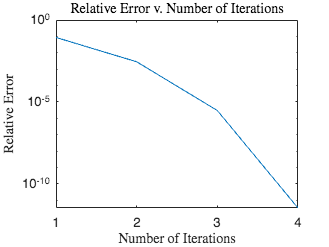

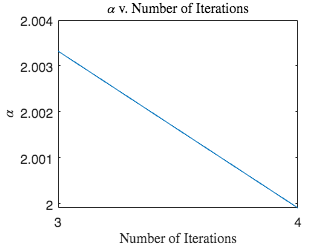

Root found by Newton after 5 iterations: 1.63672.
Approximate alpha: 1.999906


newton(f, p0, MAX_ITER, TOL, 'partA-newton');

### 2.A.2

fprintf('Expect alpha = (1 + sqrt(5))/2 = 1.618');

Expect alpha = (1 + sqrt(5))/2 = 1.618

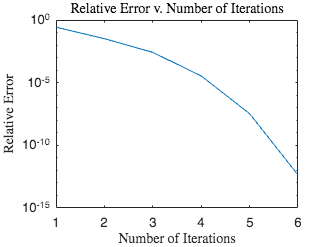

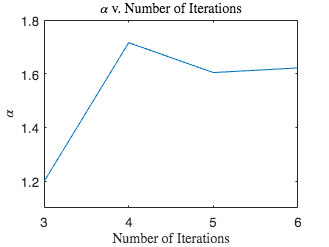

Root found by Secant after 7 iterations: 1.63672.
Approximate alpha: 1.621579


secant(f, a, b, MAX_ITER, TOL, 'partA-secant');

### 2.A.3

u = f/diff(f);
g = x - u/diff(u);

lambda = eval(subs(diff(g, 2), p)) / 2;
fprintf('Expect alpha = 2');

Expect alpha = 2

fprintf('Expect g''(p) to be zero: %f', eval(subs(diff(g), p)));

Expect g'(p) to be zero: 0.000000

fprintf('Expect lambda for Modified Newton to be g''''(p)/2: %f', lambda);

Expect lambda for Modified Newton to be g''(p)/2: -0.230168

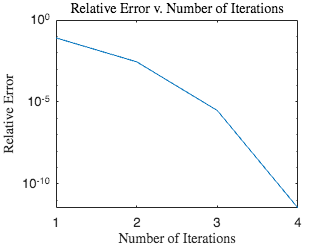

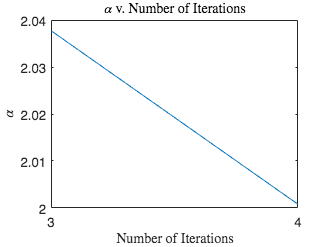

Root found by Modified Newton after 5 iterations: 1.63672.
Approximate alpha: 2.000795


modified_newton(f, p0, MAX_ITER, TOL, 'partA-modNewton');

### 2.A.4

g = x - f/diff(f) - f^2 * diff(f, 2)/(2 * diff(f)^3);

lambda = eval(subs(diff(g, 3), p)) / 6;
fprintf('Expect alpha = 3');

Expect alpha = 3

fprintf('Expect g''(p) to be zero: %f', eval(subs(diff(g), p)));

Expect g'(p) to be zero: 0.000000

fprintf('Expect g''''(p) to be zero: %f', eval(subs(diff(g, 2), p)));

Expect g''(p) to be zero: 0.000000

fprintf('Expect lambda for Cubic Newton to be g''''''(p)/6: %f', lambda);

Expect lambda for Cubic Newton to be g'''(p)/6: 0.121748

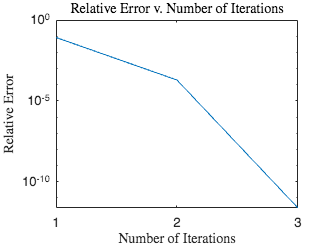

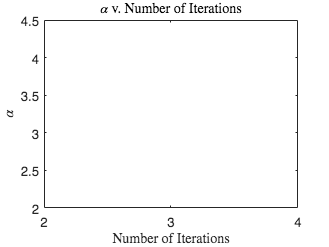

Root found by Cubic Newton after 4 iterations: 1.63672.
Approximate alpha: 3.004414


cubic_newton(f, p0, MAX_ITER, TOL, 'partA-cubNewton');

## 2.B

*Graphing f(x) and f'(x) *

f = ((x + cos(x)) * exp(-x^2) + x*cos(x))^2;
fprintf('Expect f''(p) to be zero: %f', eval(subs(diff(f), p)));

Expect f'(p) to be zero: 0.000000

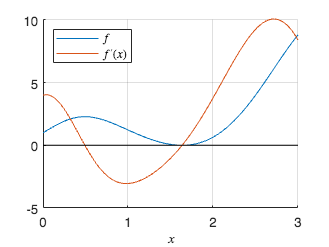


% Graph of f(x) and f'(x)
figure
hold on

fplot(f, [0 3])
fplot(diff(f), [0 3])
line([3,0], [0 0], 'Color', 'black'); % x axis
xlabel('$x$', 'interpreter', 'latex');
legend('$f$', '$f''(x)$', 'interpreter', 'latex', 'Location', 'northwest');

grid on
hold off

saveas(gcf, 'part-b-function.png');

### 2.B.1

g = x - f/diff(f);

lambda = eval(subs(diff(g), p));
fprintf('Expect alpha = 1');

Expect alpha = 1

fprintf('Expect lambda for Newton to be g''(p): %f', lambda);

Expect lambda for Newton to be g'(p): 0.500000

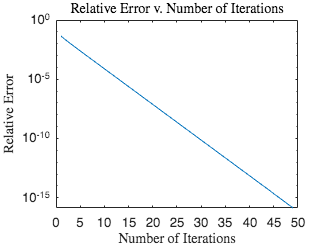

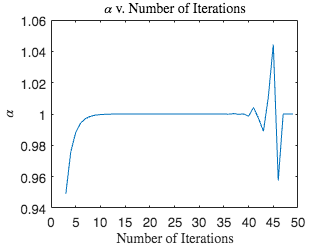

Root found by Newton after 49 iterations: 1.63672.
Approximate alpha: 1.000000


newton(f, p0, MAX_ITER, TOL, 'partB-newton');

### 2.B.2

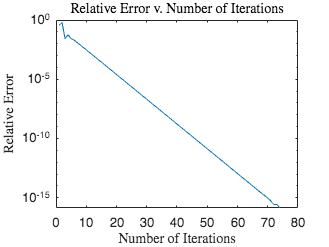

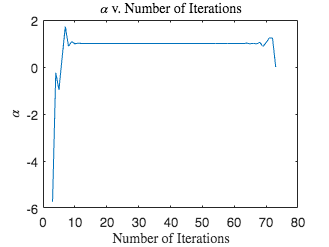

Root found by Secant after 74 iterations: 1.63672.
Approximate alpha: -0.000000

secant(f, a, b, MAX_ITER, TOL, 'partB-secant');

### 2.B.3

u = f/diff(f);
g = x - u/diff(u);

lambda = eval(subs(diff(g, 2), p)) / 2;
fprintf('Expect alpha = 2');

Expect alpha = 2

fprintf('Expect g''(p) to be zero: %f', eval(subs(diff(g), p)));

Expect g'(p) to be zero: 0.000000

fprintf('Expect lambda for Modified Newton to be g''''(p)/2: %f', lambda);

Expect lambda for Modified Newton to be g''(p)/2: -0.230168

Root found by Modified Newton after 5 iterations: 1.63672.
Approximate alpha: 2.000795


modified_newton(f, p0, MAX_ITER, TOL, 'partB-modNewton');

### 2.B.4

g = x - f/diff(f) - f^2 * diff(f, 2)/(2 * diff(f)^3);

lambda = eval(subs(diff(g), p));
fprintf('Expect alpha = 1');

Expect alpha = 1

fprintf('Expect lambda for Cubic Newton to be g''(p): %f', lambda);

Expect lambda for Cubic Newton to be g'(p): 0.375000

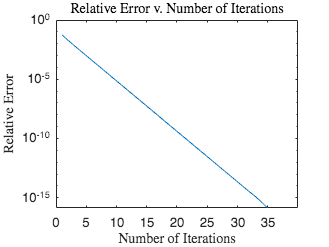

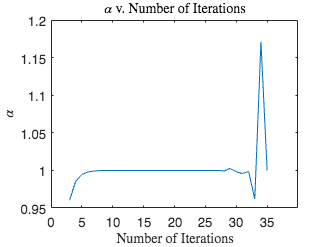

Root found by Cubic Newton after 35 iterations: 1.63672.
Approximate alpha: 1.170892


cubic_newton(f, p0, MAX_ITER, TOL, 'partB-cubNewton');

## 3

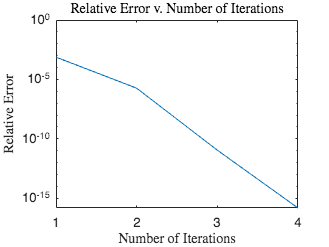

syms theta2 theta3;

r1 = 45;
r2 = 32;
r3 = 33;
r4 = 21;

theta = deg2rad(80);
theta4 = theta + pi;

F = [r2*cos(theta2) + r3*cos(theta3) + r4*cos(theta4) - r1;
    r2*sin(theta2) + r3*sin(theta3) + r4*sin(theta4)];

x0 = [deg2rad(59); deg2rad(348)];

[n, pn, errors] = nonlinear_newton(F, [theta2; theta3], x0, 10, TOL);

plot_errors(n, errors, 'nonlinear-err.png'); 

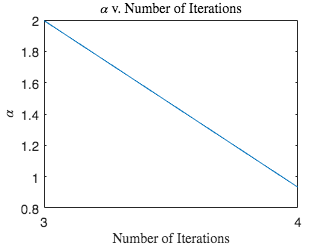

writematrix(errors, 'nonlinear-err.csv');

alphas = plot_alphas(n, errors, 'nonlinear-alpha.png');

writematrix(alphas, 'nonlinear-alpha.csv');
 
fprintf('Root found by Nonlinear Newton after %d iterations: [theta2, theta3] = [%s]', n, join(string(pn), ' '));

Root found by Nonlinear Newton after 4 iterations: [theta2, theta3] = [1.0342 6.075]

fprintf('Root found, in degrees: [theta2 theta3] = [%0.5f %0.5f].', rad2deg(pn));

Root found, in degrees: [theta2 theta3] = [59.25432 348.07065].

fprintf('\nApproximate alpha: %f', alphas(end-1));


Approximate alpha: 1.996428

## Functions

function [n, p, errors] = newton(f, p0, max_iter, tol, fileprefix) 
    %{ 
    Approximates root p of f using Newton's method. 
    Based on Algorithm 2.3 from Burden & Faires.
    
    Parameters:
    - g: fixed-point function, as a symbolic expression
    - p0: initial approximation of root p
    - max_iter: maximum number of iterations
    - tol: tolerance
    - fileprefix: prefix for output files
    
    Returns:
    - n: number of iterations until dist(p_n, p_(n-1)) < tol
    - p: approximation of p after n iterations
    - errors: array containing error after each iteration 
    %} 

    errors = zeros(max_iter, 1);
    Df = diff(f);

    for n = 1:max_iter
        p = p0 - eval(subs(f, p0) / subs(Df, p0));
        
        errors(n) = abs((p - p0) / p);
        if (errors(n) < tol)
            break;
        end

        p0 = p;
    end

    print_results('Newton', p, n, errors, fileprefix);
end

function [n, p, errors] = secant(f, p0, p1, max_iter, tol, fileprefix)
%{ 
    Approximates root p of f using the Secant method. 
    Based on Algorithm 2.4 from Burden & Faires.
    
    Parameters:
    - f: function
    - p0: first initial approximation of root p
    - p1: second initial approximation of root p
    - max_iter: maximum number of iterations
    - tol: tolerance
    - fileprefix: prefix for output files
    
    Returns:
    - n: number of iterations until dist(p_n, p_(n-1)) < tol
    - p: approximation of p after n iterations
    - errors: array containing error after each iteration
    %} 

    errors = zeros(max_iter, 1);
    q0 = eval(subs(f, p0));
    q1 = eval(subs(f, p1));

    for n = 1:max_iter
        p = p1 - q1 * (p1 - p0) / (q1 - q0);
        
        errors(n) = abs((p - p1)/p);
        if (errors(n) < tol)
            break;
        end

        p0 = p1;
        q0 = q1;
        p1 = p;
        q1 = eval(subs(f, p));
    end

    print_results('Secant', p, n, errors, fileprefix);
end

function [n, p, errors] = modified_newton(f, p0, max_iter, tol, fileprefix)
    %{ 
    Approximates root p of f using Modified Newton's method. 
    
    Parameters:
    - f: function
    - p0: first initial approximation of root p
    - p1: second initial approximation of root p
    - max_iter: maximum number of iterations
    - tol: tolerance
    - fileprefix: prefix for output files
    
    Returns:
    - n: number of iterations until dist(p_n, p_(n-1)) < tol
    - p: approximation of p after n iterations
    - errors: array containing error after each iteration 
    %} 

    errors = zeros(max_iter, 1);
    Df = diff(f);
    
    u = f/Df;
    Du = diff(u);

    for n = 1:max_iter
        p = p0 - eval(subs(u, p0)) / eval(subs(Du, p0));
        
        errors(n) = abs((p - p0)/p);
        if (errors(n) < tol)
            break;
        end

        p0 = p;
    end

    print_results('Modified Newton', p, n, errors, fileprefix);
end

function [n, p, errors] = cubic_newton(f, p0, max_iter, tol, fileprefix) 
    %{ 
    Approximates root p of f using a variant of Newton's method that
    converges cubically.
    
    Parameters:
    - f: function
    - p0: first initial approximation of root p
    - p1: second initial approximation of root p
    - max_iter: maximum number of iterations
    - tol: tolerance
    - fileprefix: prefix for output files
    
    Returns:
    - n: number of iterations until dist(p_n, p_(n-1)) < tol
    - p: approximation of p after n iterations
    - errors: array containing error after each iteration 
    %} 

    errors = zeros(max_iter, 1);
    Df = diff(f);
    D2f = diff(f, 2);

    for n = 1:max_iter
        q = eval(subs(f, p0));
        qp = eval(subs(Df, p0));
        qpp = eval(subs(D2f, p0));

        p = p0 - q/qp - q^2 * qpp / (2*qp^3);
        
        errors(n) = abs((p - p0)/p);
        if (errors(n) < tol)
            break;
        end

        p0 = p;
    end

    print_results('Cubic Newton', p, n, errors, fileprefix);
end

function [n, p, errors] = nonlinear_newton(F, vars, p0, max_iter, tol) 
    %{ 
    Approximates root p of f using Newton's method for nonlinear systems. 
    
    Parameters:
    - F: nx1 array of functions
    - vars: nx1 array of input variables for F
    - p0: initial approximation of p
    - max_iter: maximum number of iterations
    - tol: tolerance
    
    Returns:
    - n: number of iterations until dist(p_n, p_(n-1)) < tol
    - p: approximation of p after n iterations
    - errors: array containing error after each iteration
    %} 

    errors = zeros(max_iter, 1);
    
    J = jacobian(F);
    JF = [J F];         % Augumented matrix
    RJF = rref(JF);     % Reduced row echelon form of
    y = RJF(:, end);    % Symbolic solution to Jy = F
    
    for n = 1:max_iter
        p = p0 - eval(subs(y, vars, p0));
        
        errors(n) = norm(p - p0)/norm(p);
        if (errors(n) < tol)
            break;
        end

        p0 = p;
    end
end

function print_results(method, pn, n, errors, fileprefix)
    %{ 
    Graphs errors and computed alpha, and prints a summary of results.
    
    Parameters:
    - method: name of method
    - pn: final approximation of p
    - n: number of iterations
    - errors: array of errors
    - fileprefix: prefix for graph files
    
    Returns:
    - n: number of iterations until dist(p_n, p_(n-1)) < tol
    - p: approximation of p after n iterations
    - errors: array containing error after each iteration
    %} 
    
    plot_errors(n, errors, sprintf('%s-err.png', fileprefix)); 
    writematrix(errors, sprintf('%s-err.csv', fileprefix));

    alphas = plot_alphas(n, errors, sprintf('%s-alpha.png', fileprefix));
    writematrix(alphas, sprintf('%s-alpha.csv', fileprefix));
 
    fprintf('Root found by %s after %d iterations: %0.5f.', method, n, pn);
    fprintf('\nApproximate alpha: %f', alphas(end-1));
end

function plot_errors(n, errors, filename)
    %{
    Plots errors against number of iterations.
    
    Parameters:
    - n: number of iterations
    - errors: array of errors
    - filename: where to output graph
    %}

    figure
    semilogy(1:n, errors(1:n));
    
    ylabel('Relative Error', 'interpreter', 'latex');
    xlabel('Number of Iterations', 'interpreter', 'latex');
    
    title('Relative Error v. Number of Iterations', 'interpreter', 'latex');

    % Iteration number must be an integer
    xlabels = get(gca, 'xTick');
    xticks(unique(round(xlabels)));

    saveas(gcf, filename);
end

function alphas = plot_alphas(n, errors, filename)
    %{
    Plots alpha against number of iterations.
    alpha = [log(E[n+1])-log(E[n])] / [log(E[n])-log(E[n-1])]
    
    Parameters:
    - n: mumber of iterations (must be > 2)
    - errors: error array
    - filename: name of output file
    %}

    alphas = zeros(n-2, 1);
    logerrors = log(errors);
    
    prevdelta = logerrors(2) - logerrors(1);
    
    for i=2:n-1
       currdelta = logerrors(i+1) - logerrors(i);
       alphas(i-1) = currdelta / prevdelta;
       prevdelta = currdelta;
    end

    figure
    plot(3:n, alphas);
    
    ylabel('$\alpha$', 'interpreter', 'latex');
    xlabel('Number of Iterations', 'interpreter', 'latex');
    
    title('$\alpha$ v. Number of Iterations', 'interpreter', 'latex');

    % Iteration number must be an integer
    xlabels = get(gca, 'xTick');
    xticks(unique(round(xlabels)));

    saveas(gcf, filename);
end